# Integrating Antenna Arrays with Phased Array Algorithms

Design an array with 8 dipoles operating at 5GHz.

F0 = 5e9;
f = linspace(0.95*F0, 1.05*F0, 101);
l = design(linearArray, F0, dipole)

l =   linearArray with properties:

           Element: [1×1 dipole]
       NumElements: 2
    ElementSpacing: 0.0300
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


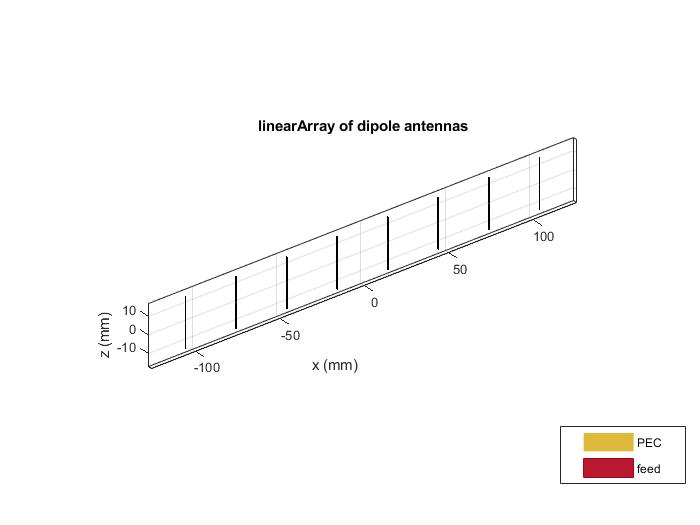

l.NumElements = 8;
show(l);

Compute and visualize the S-parameters of the array.

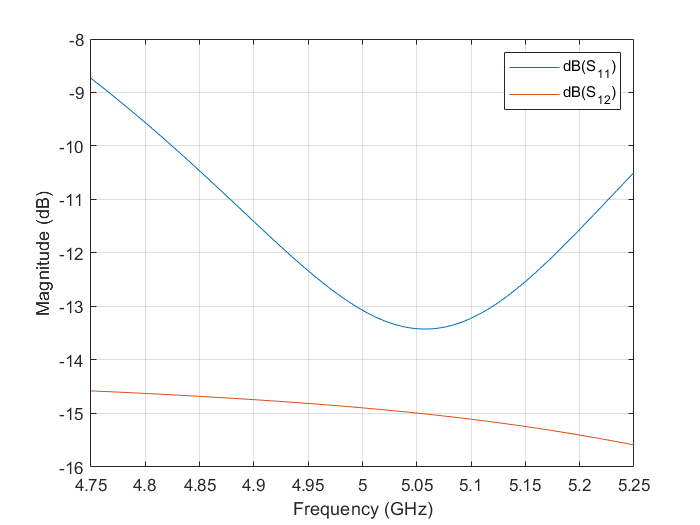

s = sparameters(l,f);
rfplot(s, 1, 1);
hold on;
rfplot(s, 1, 2);

Compute and visualize the full-array far-field radiation pattern.

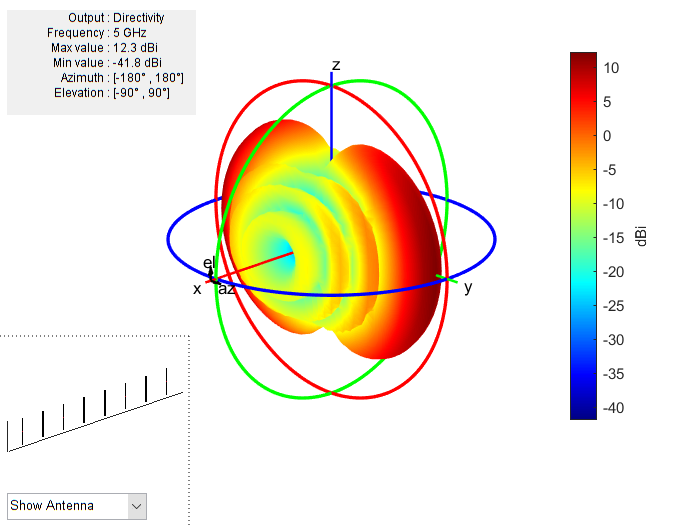

pattern(l, F0);

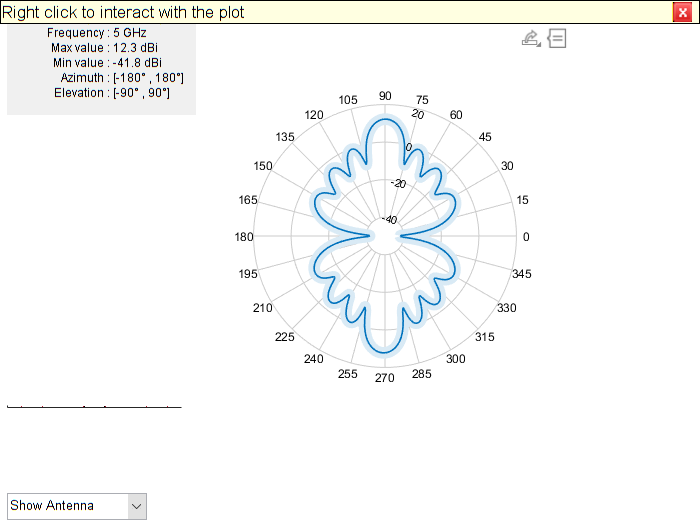

p1 = patternAzimuth(l, F0, 0);
P = polarpattern(p1);

Build a phased array object suitable for signal processing.

u = phased.ULA;
u.NumElements = 8;
u.Element = design(dipole, F0);
u.ElementSpacing = l.ElementSpacing;
u.ArrayAxis = 'x';

Compute the pattern and compare with the full-field solution

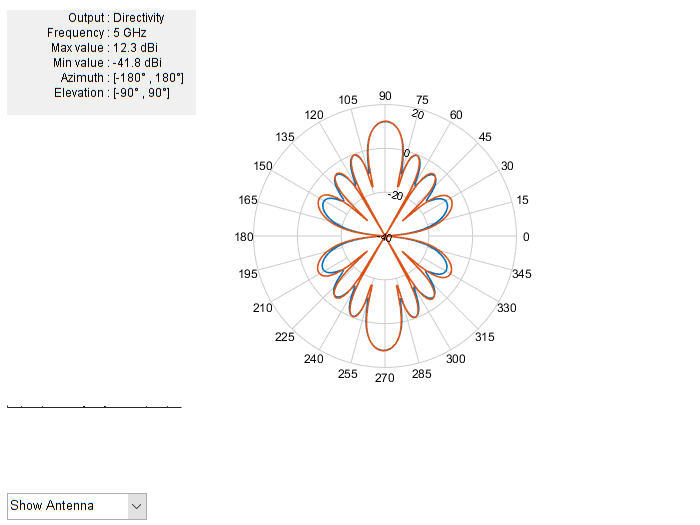

p2 = patternAzimuth(u, F0, 0);
add(P,p2)
P.MagnitudeLim = [-40 20];

Open the Simulink model and inspect the RF receiver.

open_system('MIMOSystemAntenna')